# Generating 5G Waveforms

You can easily generate waveforms with the 5G Toolbox. Here is a list of waveforms you can generate:

- Test models

- FRCs (uplink and downlink)

- Downlink waveforms 

- Uplink waveforms

- PRACH waveforms

These waveforms are fully configurable. You can generate waveforms

- Using the wireless waveform generator app

- Using the programatic interface (`nrWaveformGenerator)`

Use these waveform generators to create waveforms for T&M applications. These waveforms have finite length and are generated with a static set of parameters. If you want to create waveforms with dynamically changing parameters, like those used to model a 5G link, refer to the "NR PDSCH Throughput" example. 

## Generating waveforms using the wireless waveform generator app

The  wireless waveform generator app provides a convenient way to deal with the large number of parameters needed.

Open the 5G waveform generator from the App tab.

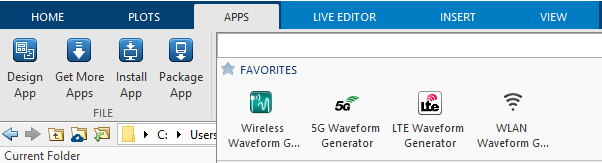

This opens the App. You can specify the required parameters and generate the waveform by clicking on  "Generate"

### Specifying parameters

You can specify the required parameters on the UI. The Downlink and Uplink options allow you to fully customise the contents of your waveform. You can also generate Test models or FRCs, where the number of parameters is reduced.

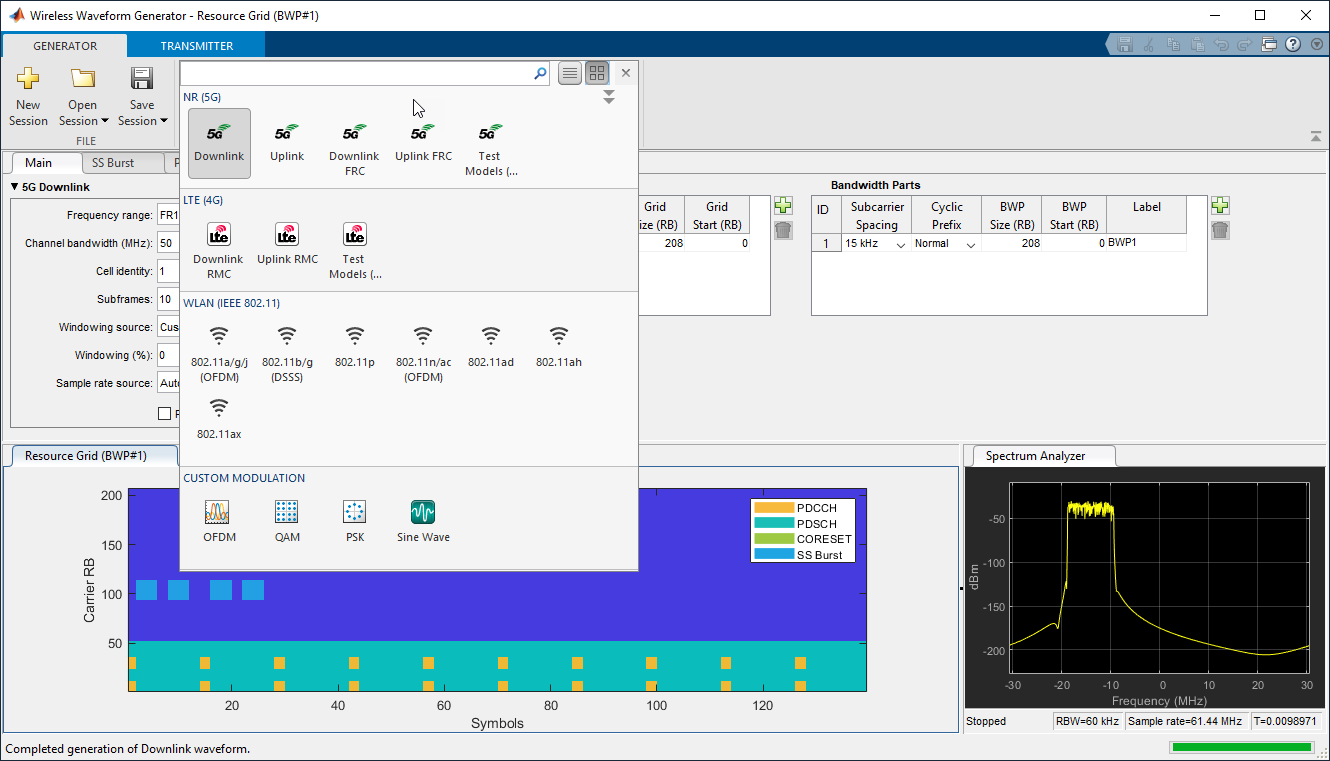

### Generating and exporting the waveform

Click on the Generate button to generate the waveform. This creates the baseband IQ samples internally in the generator. If you want to use this signal in MATLAB or save it to file you have the following Export options:

- Export to workspace: creates a structure in MATLAB's workspace with the waveform, its sampling frequency, its configuration parameters and a string describing the type of waveform (downlink, uplink, test model, downlink FRC or uplink FRC)

                 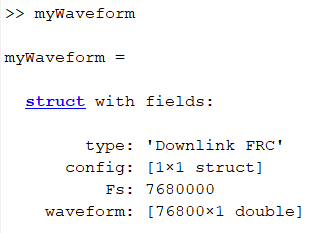

- Export to file: save as a `.mat` or a `.bb` file (link to what this is https://uk.mathworks.com/help/comm/ref/comm.basebandfilewriter-system-object.html)

- Export to MATLAB script: create a MATLAB script which generates the specified waveform when executed

## Generating waveforms using the programatic interface

A programatic interface is available to generate waveforms. 

Create an instance of a waveform parameter object

waveconfig = nrDLCarrierConfig()  % Create an instance of the waveform's parameter object

waveconfig =   nrDLCarrierConfig with properties:

               Label: 'Downlink carrier 1'
      FrequencyRange: 'FR1'
    ChannelBandwidth: 50
             NCellID: 1
        NumSubframes: 10
    WindowingPercent: 0
          SampleRate: []
    CarrierFrequency: 0
         SCSCarriers: {[1×1 nrSCSCarrierConfig]}
      BandwidthParts: {[1×1 nrWavegenBWPConfig]}
             SSBurst: [1×1 nrWavegenSSBurstConfig]
             CORESET: {[1×1 nrCORESETConfig]}
        SearchSpaces: {[1×1 nrSearchSpaceConfig]}
               PDCCH: {[1×1 nrWavegenPDCCHConfig]}
               PDSCH: {[1×1 nrWavegenPDSCHConfig]}
               CSIRS: {[1×1 nrWavegenCSIRSConfig]}


The `waveconfig` object contains the full waveform specification and is fully configurable.

Once the desired values are specified, you can call the waveform generator.

[waveform,waveformInfo] = nrWaveformGenerator(waveconfig);

Plot the spectrogram to visualise the signal in the frequency domain

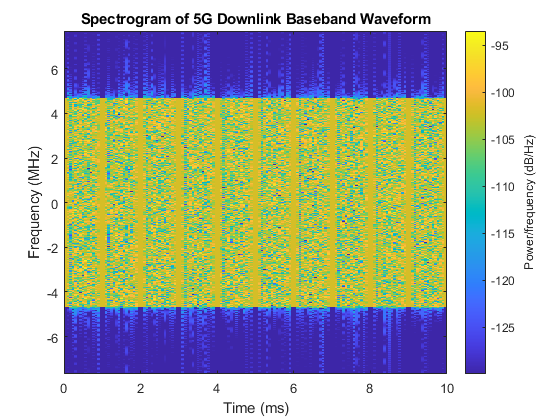

% Plot spectogram of waveform for first antenna port
samplerate = waveformInfo.ResourceGrids(1).Info.SampleRate;
nfft = waveformInfo.ResourceGrids(1).Info.Nfft;
figure;
spectrogram(waveform(:,1),ones(nfft,1),0,nfft,'centered',samplerate,'yaxis','MinThreshold',-130);
title('Spectrogram of 5G Downlink Baseband Waveform');

This waveform includes a full allocation PDSCH, a PDCCH and the SS burst. To be able to see them more clearly change the PDSCH allocation to span PRBs 0 to 10. Generate the waveform again and plot the spectrogram.

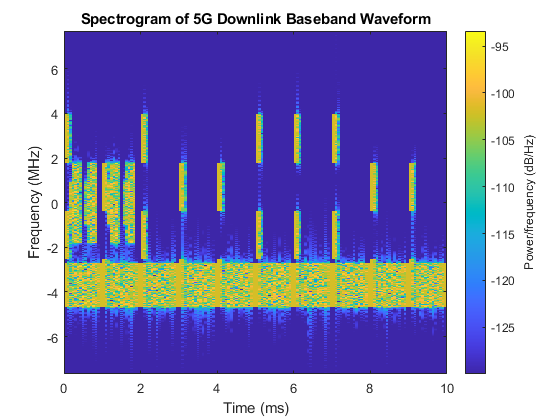

waveconfig.PDSCH{1}.PRBSet = 0:10;
[waveform,waveformInfo] = nrWaveformGenerator(waveconfig);

% Plot spectogram of waveform for first antenna port
samplerate = waveformInfo.ResourceGrids(1).Info.SampleRate;
nfft = waveformInfo.ResourceGrids(1).Info.Nfft;
figure;
spectrogram(waveform(:,1),ones(nfft,1),0,nfft,'centered',samplerate,'yaxis','MinThreshold',-130);
title('Spectrogram of 5G Downlink Baseband Waveform');

The waveform generator supports multiple instances of the physical channels and signals. Create a second instance of the PDSCH configuration object and set the allocation to span PRBs 40 to 50 and OFDM symbols 2 to 10.

mySecondPDSCH = nrWavegenPDSCHConfig();
mySecondPDSCH.PRBSet = 40:50;
mySecondPDSCH.SymbolAllocation = [2 10];

Assign the second PDSCH configuration to the waveform configuration instance and generate the waveform.

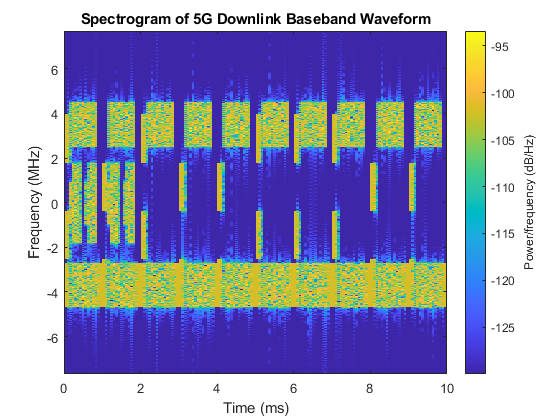

waveconfig.PDSCH{2} = mySecondPDSCH;
[waveform,waveformInfo] = nrWaveformGenerator(waveconfig);

% Plot spectogram of waveform for first antenna port
samplerate = waveformInfo.ResourceGrids(1).Info.SampleRate;
nfft = waveformInfo.ResourceGrids(1).Info.Nfft;
figure;
spectrogram(waveform(:,1),ones(nfft,1),0,nfft,'centered',samplerate,'yaxis','MinThreshold',-130);
title('Spectrogram of 5G Downlink Baseband Waveform');